clear all;

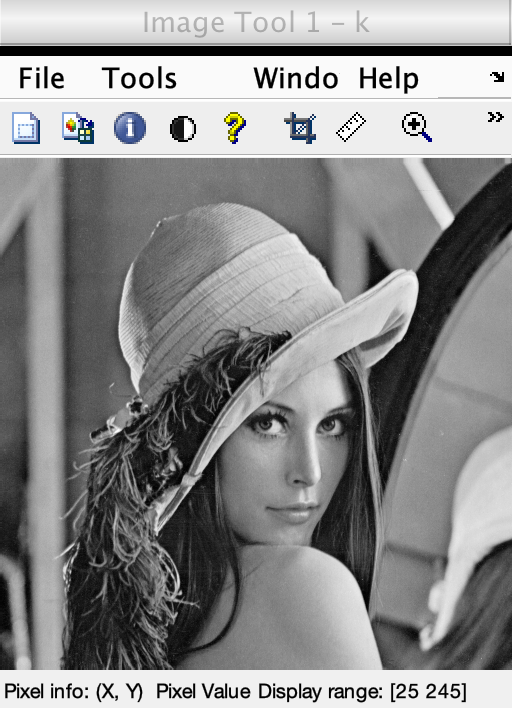

% MATLAB code for Sobel operator
% edge detection

%k=imread("city.jpg");
k=imread("Lenna.png");

k=rgb2gray(k);
k1=double(k);

s_msk=[-1 0 1; -2 0 2; -1 0 1];
kx=conv2(k1, s_msk, 'same');
ky=conv2(k1, s_msk', 'same');
ked=sqrt(kx.^2 + ky.^2);

%display the images.
imtool(k,[]);

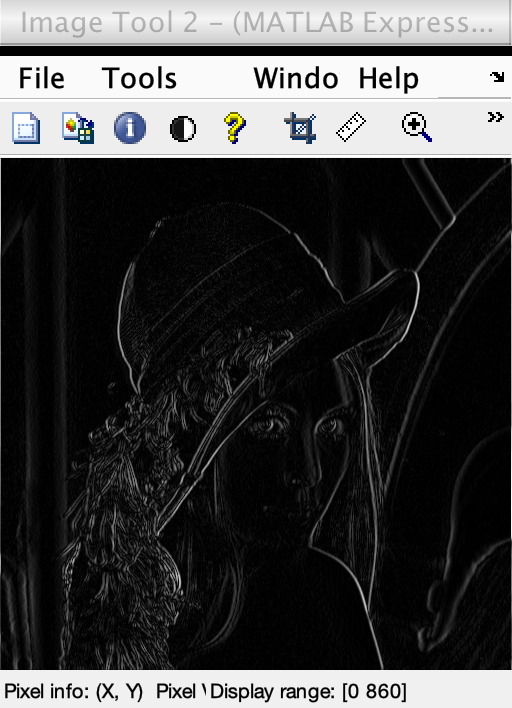


%display the edge detection along x-axis.
imtool(abs(kx), []);

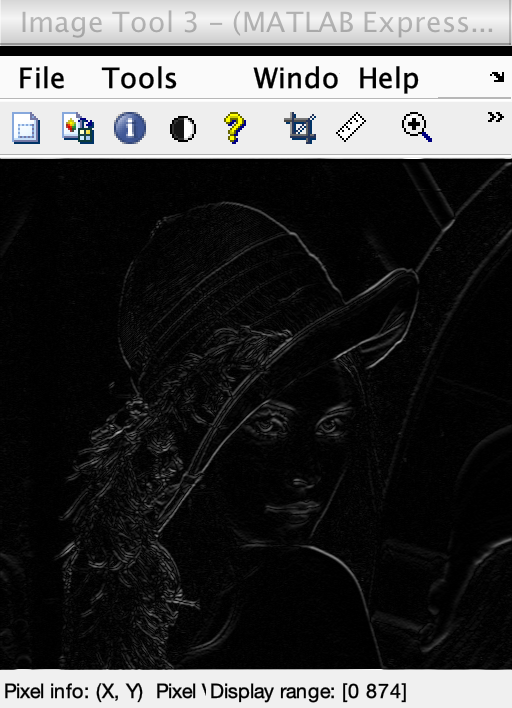


%display the edge detection along y-axis.
imtool(abs(ky),[]);


%display the full edge detection.
imtool(abs(ked),[]);
